load("..\temp-data\participant_dataset.mat")

for j = 1:length(participant_list)
    ml_ctrl_data = participant_list(j).machine_experiment.control_task.data_tbl;
    cl_ctrl_data = participant_list(j).mutual_experiment.control_task.data_tbl;
    hl_ctrl_data = participant_list(j).human_experiment.control_task.data_tbl;
    ml_expl_data = participant_list(j).machine_experiment.experimental_task.data_tbl;
    cl_expl_data = participant_list(j).mutual_experiment.experimental_task.data_tbl;
    hl_expl_data = participant_list(j).human_experiment.experimental_task.data_tbl;

    participant(j).ml_ctrl_ttbl = make_ttbl(ml_ctrl_data, "Machine");
    participant(j).cl_ctrl_ttbl = make_ttbl(cl_ctrl_data, "Co-Adaptive");
    participant(j).hl_ctrl_ttbl = make_ttbl(hl_ctrl_data, "Human");
    participant(j).ml_expl_ttbl = make_ttbl(ml_expl_data, "Machine");
    participant(j).cl_expl_ttbl = make_ttbl(cl_expl_data, "Co-Adaptive");
    participant(j).hl_expl_ttbl = make_ttbl(hl_expl_data, "Human");
end

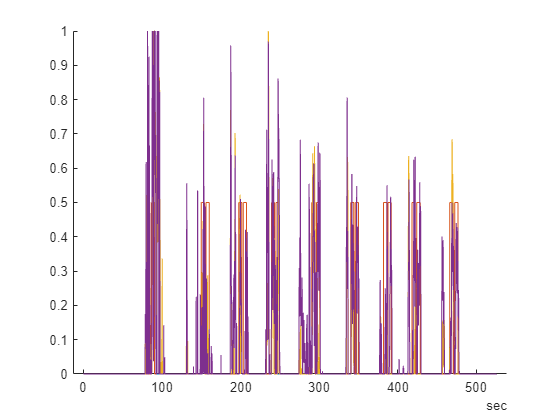

figure
fig_tbl = participant(j).cl_expl_ttbl;
plot(fig_tbl.Time, fig_tbl.("Kinematics (Des)"))
hold on
plot(fig_tbl.Time, fig_tbl.("Kinematics (Pred)"))
hold off
box off

THEME.BLACK = [0.0941, 0.0941, 0.0941];
THEME.BLUE = [0.0510, 0.2078, 0.5020];
THEME.RED = [0.8235, 0.1608, 0.1765];
THEME.WIDTH = 2.5;
plot(kin_t, kin_desired(:,2), Color=THEME.RED, LineWidth=THEME.WIDTH)
hold on
plot(kin_t, kin_desired(:,1), Color=THEME.BLUE, LineWidth=THEME.WIDTH)
hold off
box off
legend([DOF_B.LABEL, DOF_A.LABEL])

function task_ttbl = make_ttbl(task_data, task_label)
DOF_A.IDX = 5; % Pinky -> Power grasp
DOF_A.LABEL = "Power";
DOF_B.IDX = 1; % Thumb -> Precission grasp
DOF_B.LABEL = "Precision";

kin_t = task_data.Time;
kin_desired = task_data(:,"Targets").Variables;
kin_desired = kin_desired(:,[DOF_A.IDX, DOF_B.IDX]);
if (any(kin_desired(1,:))); kin_desired(1,:) = 0; warning("Removed initial datapoints");end

task_ttbl = array2timetable(kin_desired, "VariableNames", [DOF_A.LABEL, DOF_B.LABEL], "RowTimes",kin_t);
task_ttbl = mergevars(task_ttbl, task_ttbl.Properties.VariableNames, "NewVariableName","Kinematics (Des)");

features = task_data(:,"Features").Variables;
task_ttbl = [task_ttbl table(features(:,193:224), VariableNames="Features")];
temp = task_ttbl.("Kinematics (Des)");
task_ttbl.Gesture(temp(:,2)==0) = "Rest";
task_ttbl.Gesture(temp(:,2)>0) = "Precision";
task_ttbl.Gesture(temp(:,1)>0) = "Power";

dof_a.starts = find(diff(kin_desired(:,1))>0);
dof_a.stops = find(diff(kin_desired(:,1))<0);
dof_b.starts = find(diff(xor(kin_desired(:,1), kin_desired(:,2)))>0);
dof_b.stops = find(diff(xor(kin_desired(:,1), kin_desired(:,2)))<0);

task_ttbl.Task(:) = task_label;

if task_label=="Machine"
    for i=1:length(dof_a.starts)
        task_ttbl.Trial(dof_a.starts(i):dof_b.stops(i)) = sprintf("Trial %d", i-1);
    end
    kalman_mask = ~cellfun(@isempty, regexp(task_data.Properties.VariableNames, 'Kalman'));
    kalman_vars = task_data.Properties.VariableNames(kalman_mask);
    kalman = task_data(:, kalman_vars(1)).Variables;
    kin_predicted = kalman(:, [DOF_A.IDX, DOF_B.IDX]);
    kalman_tbl = mergevars(array2table(kin_predicted),[1,2], 'NewVariableName', sprintf("Kalman %0d", 1));

    for i=2:length(kalman_vars)
        kalman = task_data(:, kalman_vars(i)).Variables;
        kin_predicted = kalman(:, [DOF_A.IDX, DOF_B.IDX]);
        kalman_tbl = [kalman_tbl, mergevars(array2table(kin_predicted),[1,2],'NewVariableName', sprintf("Kalman %0d", i))];
    end

    kalman_tbl.Kalman = kalman_tbl.("Kalman 9");
    for i = 8:-1:1
        idx_range = 1:find(task_ttbl.Trial == "Trial " + i, 1, "last");
        kalman_selected = kalman_tbl.("Kalman " + i);
        kalman_tbl.Kalman(idx_range) = kalman_selected(idx_range);
    end
else
    for i=1:length(dof_a.starts)
        task_ttbl.Trial(dof_a.starts(i):dof_b.stops(i)) = sprintf("Trial %d", i);
    end
    kalman = task_data.Kalman;
    kin_predicted = kalman(:, [DOF_A.IDX, DOF_B.IDX]);
    kalman_tbl = mergevars(array2table(kin_predicted),[1,2], 'NewVariableName', "Kalman");
end
kalman_tbl = renamevars(kalman_tbl, "Kalman", "Kinematics (Pred)");
task_ttbl = [task_ttbl, kalman_tbl];
task_ttbl = movevars(task_ttbl, {'Gesture', 'Trial', 'Task'}, "After","Kinematics (Pred)");
end